# Horizontal line scan data

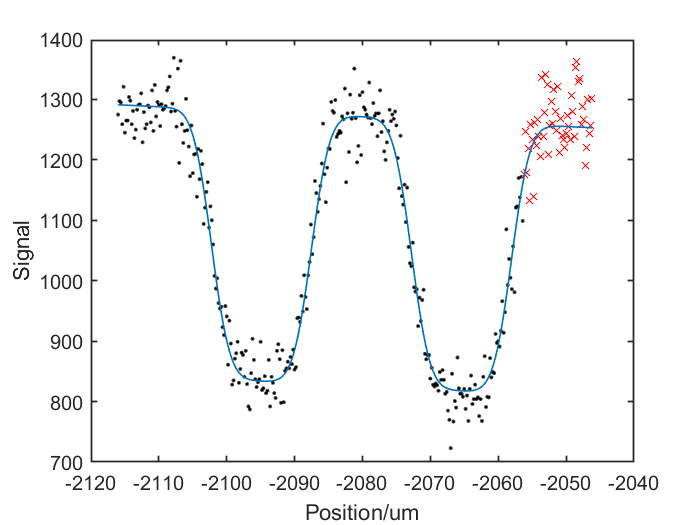

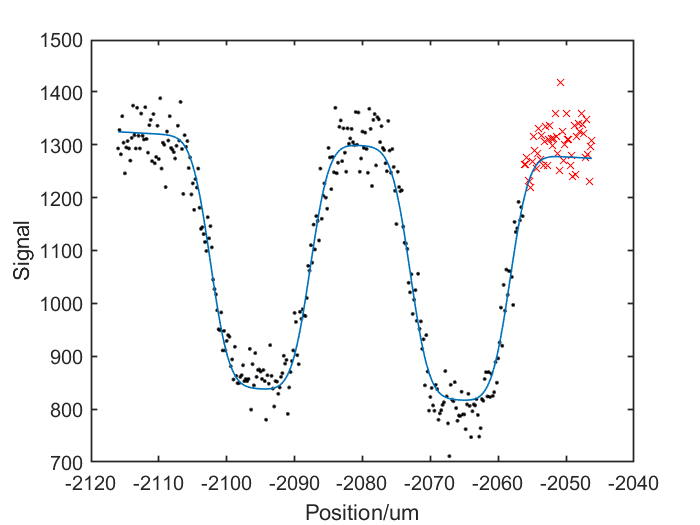

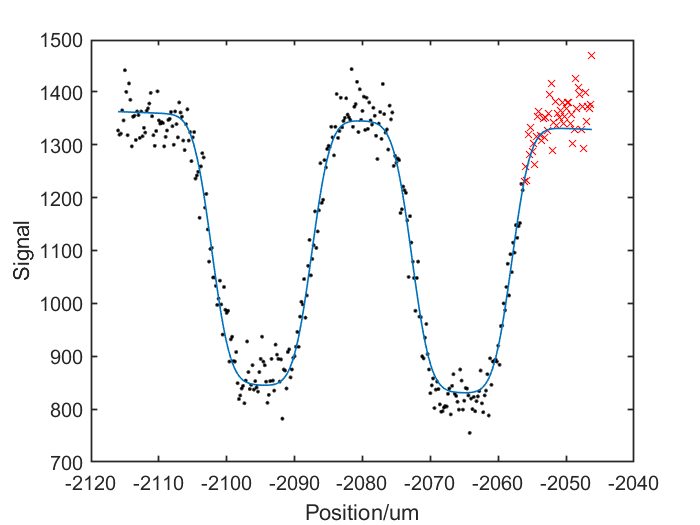

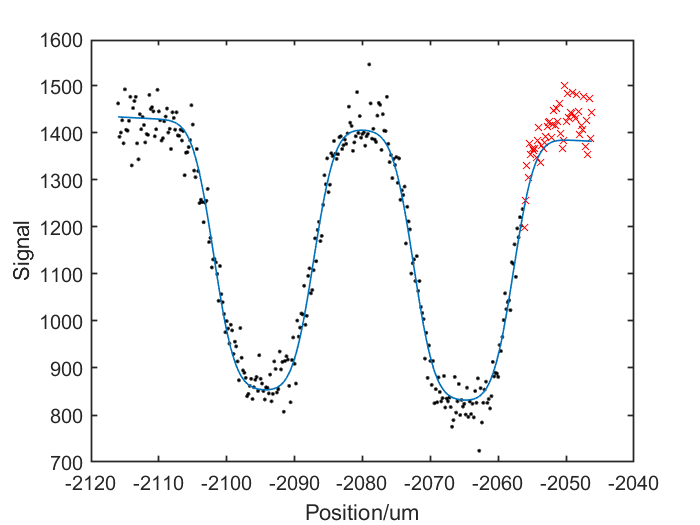

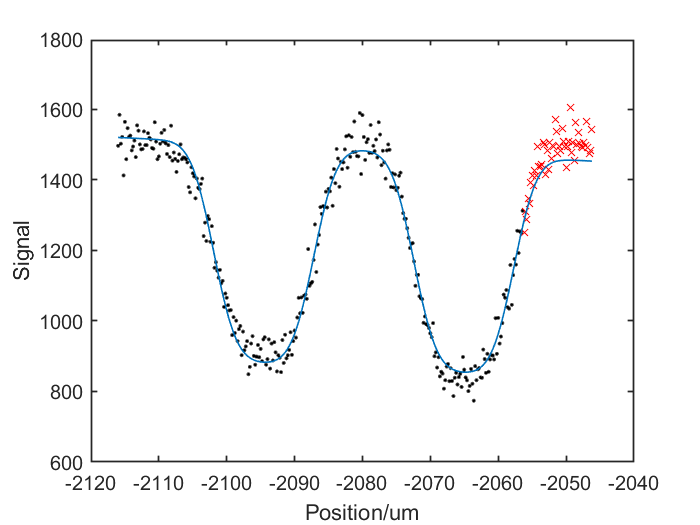

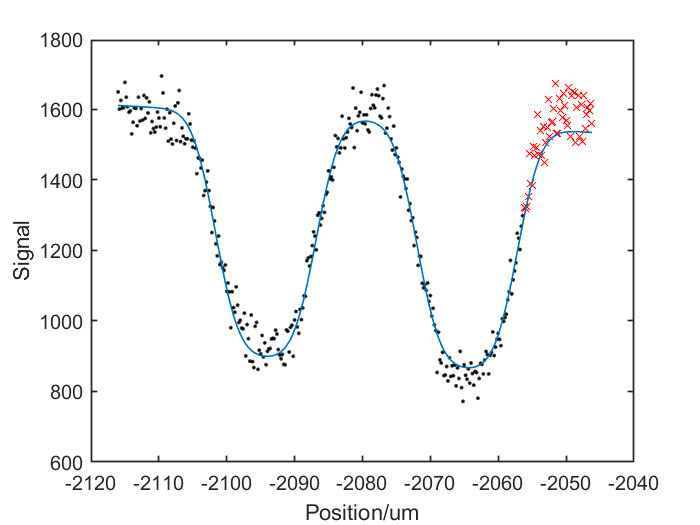

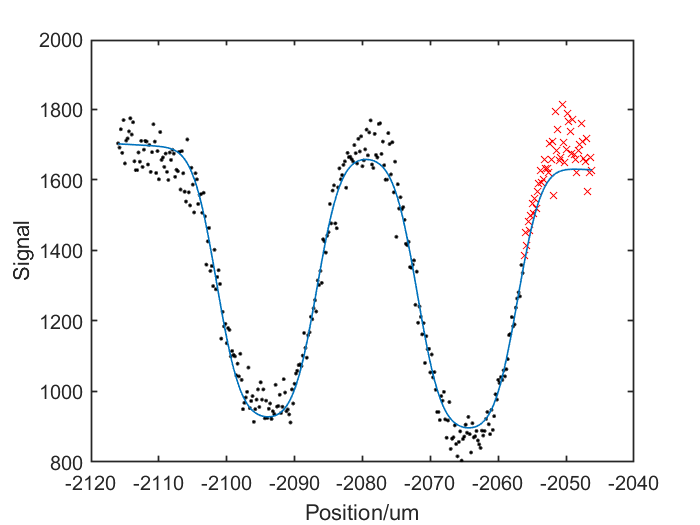

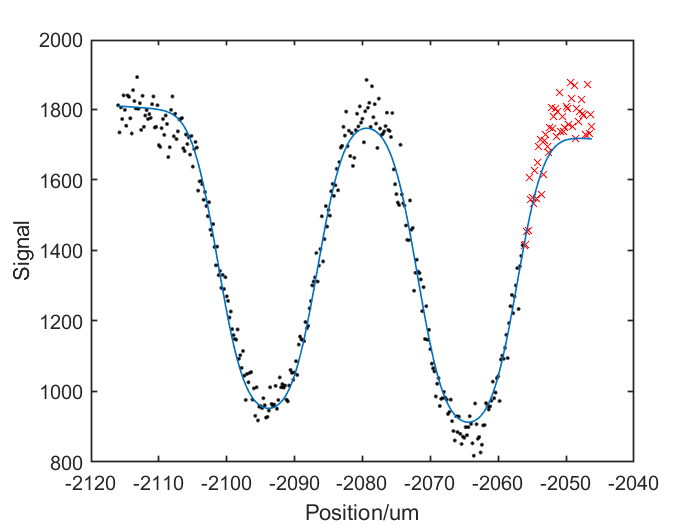



%data=read_LSN_data('Data\11-Feb-2021_002.lsn');
data=read_LSN_data('Data\16-Feb-2021_002.lsn');

%Set the z positions of the scans
%Grab number of points and spacing of them
delta_z=data.step_size(2);
N_z=data.num_pixels(2);

%Generate the x positions of each data point
z=data.start(3):delta_z:data.start(3)+delta_z*(N_z-1);

%x positions
%Grab number of points and spacing of them
delta=data.step_size(1);
N=data.num_pixels(1);

%Generate the x positions of each data point
x=data.start(1):-delta:data.start(1)-delta*(N-1);
%figure;plot(x,data.image)
%figure;plot(data.image(:,1))

%Initialise memory
sigma_z=NaN*ones(1,N_z);
sigma_z_error=NaN*ones(1,N_z);
mu_z=NaN*ones(1,N_z);
mu_z_error=NaN*ones(1,N_z);
a_z=NaN*ones(1,N_z);
a_z_error=NaN*ones(1,N_z);
c_z=NaN*ones(1,N_z);
c_z_error=NaN*ones(1,N_z);


%Main loop over each dataset
for n=1:N_z
    

    %Choose where to crop the data off to only include the 15um slits
    slit_15_end=350;
    y_crop=data.image(1:slit_15_end,n);
    x_crop=x(1:slit_15_end);
    
    %Set point near the edge so there is no influence from the 10um slits
    %when the beam gets very large
    slit_15_mid=300;
    
    N_crop=length(y_crop);
    
    % Fit 4 error functions to the data to estimate the width and position
    [xData, yData] = prepareCurveData( x_crop, y_crop );
    
    % Set up fittype and options.
    ft = fittype( 'a*(normcdf(x,mu,sigma)-normcdf(x,mu+d,sigma)+normcdf(x,mu+2*d,sigma)-normcdf(x,mu+3*d,sigma))+m*(x-mu)+c', 'independent', 'x', 'dependent', 'y' );
    excludedPoints = excludedata( xData, yData, 'Indices', [slit_15_mid:N_crop ] );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    %opts.StartPoint = [-300 700 12 1 -1660 2];
    opts.StartPoint = [-1000 2000 12 1 -2100 2];
    opts.Upper = [Inf Inf Inf Inf 0 Inf];
    opts.Exclude = excludedPoints;
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    %Plot the output
    figure;plot(x_crop(1:slit_15_mid-1),y_crop(1:slit_15_mid-1),'k.')
    hold on
    plot(x_crop(slit_15_mid:end),y_crop(slit_15_mid:end),'rx')
    plot(x_crop,fitresult(x_crop),'LineWidth',1,'Color',	[0, 0.4470, 0.7410])
    xlabel('Position/um')
    ylabel('Signal')
    
    set(gca,'FontSize',12,'LineWidth',1)
    
    %Save outputs
    error=confint(fitresult,0.6827);
    
    sigma_z(n)=fitresult.sigma;
    sigma_z_error(n)=diff(error(:,6))/2;
    
    mu_z(n)=fitresult.mu;
    mu_z_error(n)=diff(error(:,5))/2;
    
    a_z(n)=fitresult.a;
    
    c_z(n)=fitresult.c;
    
    
end

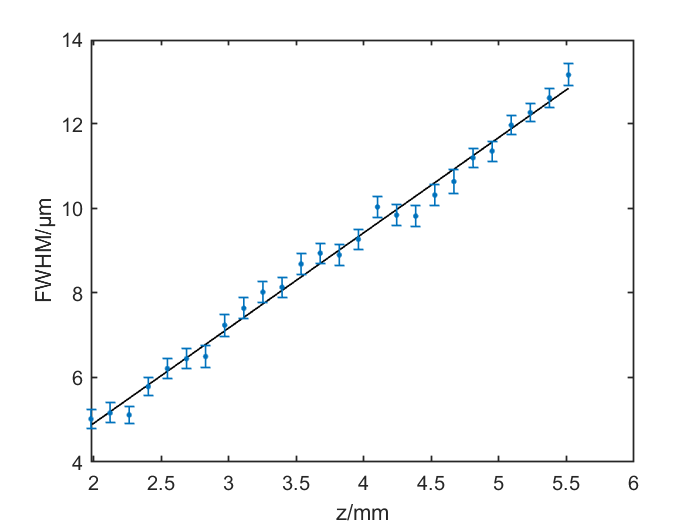


%Estimate of the true z position
z2=(4.5e3-z)*sqrt(2);

%Calculate the full width at half maximum
FWHM=sigma_z*2*sqrt(2*log(2));
FWHM_error=sigma_z_error*2*sqrt(2*log(2));


%Fit a straight line
[xData, yData] = prepareCurveData( z2, FWHM );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [19 20] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
%opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult_h, gof] = fit( xData, yData, ft, opts );

lin_error=confint(fitresult_h,0.6827);


%Plot the FWHM
figure;plot(z2/1e3,fitresult_h(z2),'k','LineWidth',1)
hold on
errorbar(z2/1e3,FWHM,FWHM_error,'.','LineWidth',1,'MarkerSize',10,'Color',	[0, 0.4470, 0.7410])
%errorbar(z2(19:20)/1e3,FWHM(19:20),FWHM_error(19:20),'.','LineWidth',1,'MarkerSize',10,'Color',	[1, 0, 0])
ylabel(['FWHM/',char(181),'m'])
xlabel(['z/mm'])
%xlim([0 4])
%ylim([0 14])
set(gca,'FontSize',12,'LineWidth',1)


% %Estimate the pinhole size
% d=fitresult_h.p2*sqrt(3)/(sqrt(2*log(2)));
% d_error=(diff(lin_error(:,2))/2)*sqrt(3)/(sqrt(2*log(2)));

%Estimate angular source size
beta=fitresult_h.p1*sqrt(3)/(2*sqrt(2*log(2)));
beta_error=(diff(lin_error(:,1))/2)*sqrt(3)/(2*sqrt(2*log(2)));

beta_fwhm=fitresult_h.p1;
beta_error_fwhm=(diff(lin_error(:,1))/2);


%Estimate the size of the skimmer
L=68e-3

L = 0.0680

L_error=2e-3;
r_skim_guess=beta*L;
r_skim_guess_error_frac=sqrt((beta_error/beta)^2+(L_error/L)^2);
r_skim_guess_error = r_skim_guess_error_frac*r_skim_guess;

d_skim_guess=r_skim_guess*2;
d_skim_guess_error=r_skim_guess_error*2;


# Vertical line scan data

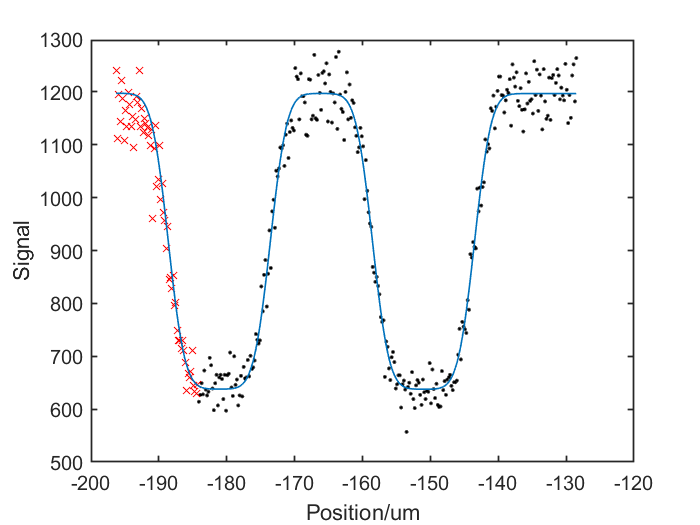

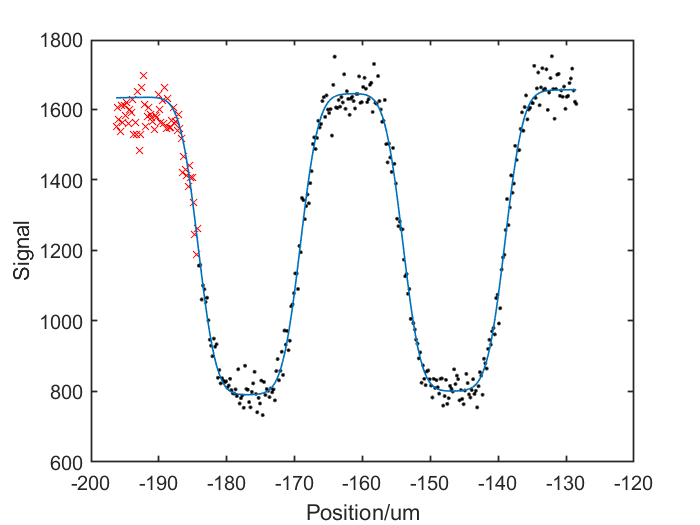

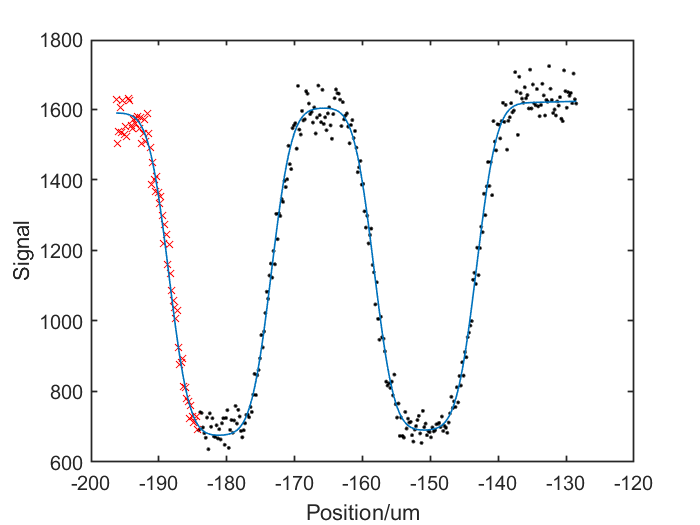

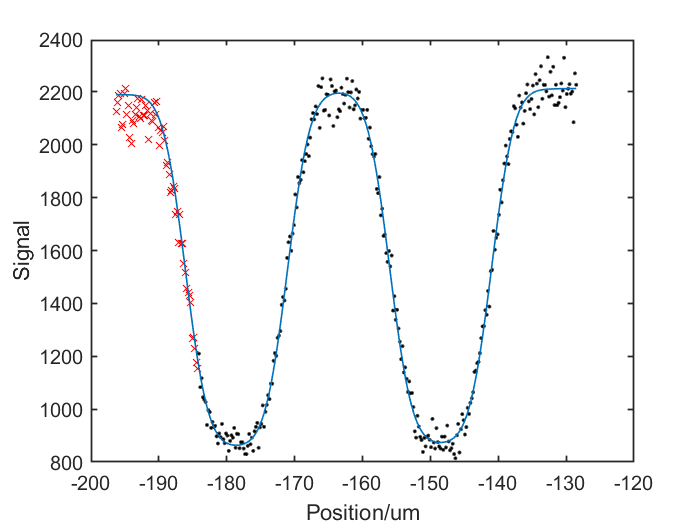

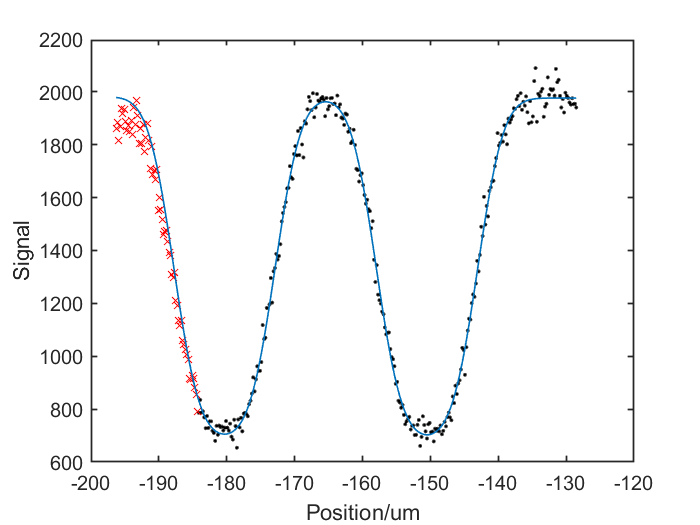

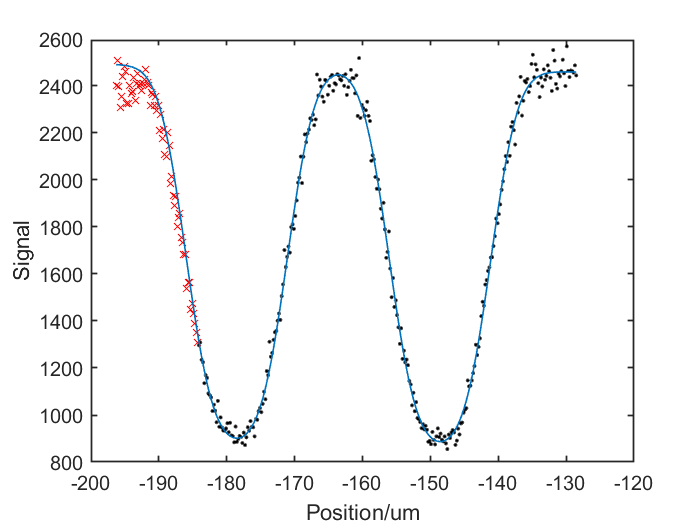

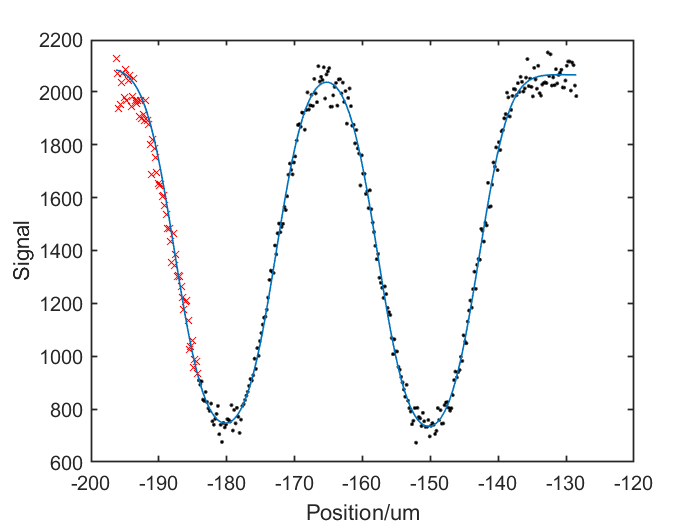

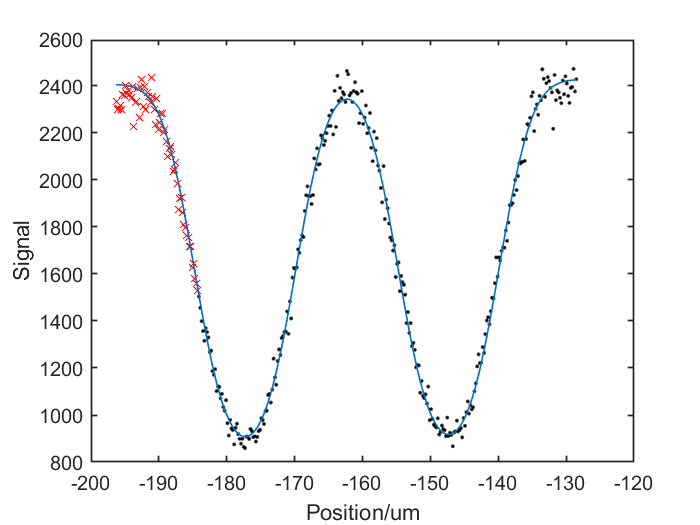


%Set the z positions of the scans
%z=[2.5,2,1.5,1]*1e3;
z_v=[2.75:-0.25:1]*1e3;

N_z_v=length(z_v);

%Initialise memory
sigma_z_v=NaN*ones(1,N_z_v);
sigma_z_error_v=NaN*ones(1,N_z_v);
mu_z_v=NaN*ones(1,N_z_v);
mu_z_error_v=NaN*ones(1,N_z_v);

data_large1_v=NaN*ones(800,N_z_v);
data_large2_v=NaN*ones(800,N_z_v);

data=read_MkII_data('Data\23-Feb-2021_001.txt');

%Grab number of points and spacing of them
delta=data.step_size(2);
N=length(data.image);

%Generate the x positions of each data point
x=data.start(2):-delta:data.start(2)-delta*(N-1);
%figure;plot(x,data.image)

%Main loop over each dataset
for n=1:N_z_v
    
    %Kind of dirty way to load each data set in. Yes, I could use the
    %initial positions instead.
    switch n
        case 2
            data=read_MkII_data('Data\09-Feb-2021_004.txt');
        case 4
            data=read_MkII_data('Data\11-Feb-2021_001.txt');
        case 6
            data=read_MkII_data('Data\11-Feb-2021_002.txt');
        case 8
            data=read_MkII_data('Data\09-Feb-2021_013.txt');
        case 1
            data=read_MkII_data('Data\23-Feb-2021_001.txt');
        case 3
            data=read_MkII_data('Data\23-Feb-2021_002.txt');
        case 5
            data=read_MkII_data('Data\23-Feb-2021_003.txt');
        case 7
            data=read_MkII_data('Data\23-Feb-2021_004.txt');
    end
    
    
    data_large1_v(:,n)=data.image(1,:);
    data_large2_v(:,n)=data.image(2,:);
    
    %Take average of the two lines
    %data.image=mean(data.image);
    data.image=data.image(1,:);
    
    %Grab number of points and spacing of them
    delta=data.step_size(2);
    N=length(data.image);
    
    %Generate the x positions of each data point
    %x=data.start(2):-delta:data.start(2)-delta*(N-1);
    %figure;plot(x,data.image)
    
    %Choose where to crop the data off to only include the 15um slits
    slit_15_end=340;
    y_crop=data.image(1:slit_15_end);
    x_crop=x(1:slit_15_end);
    
    %Set point near the edge so there is no influence from the 10um slits
    %when the beam gets very large
    slit_15_mid=280;
    
    N_crop=length(y_crop);
    
    % Fit 4 error functions to the data to estimate the width and position
    [xData, yData] = prepareCurveData( x_crop, y_crop );
    
    % Set up fittype and options.
    ft = fittype( 'a*(-normcdf(x,mu,sigma)+normcdf(x,mu-d,sigma)-normcdf(x,mu-2*d,sigma)+normcdf(x,mu-3*d,sigma))+m*x+c', 'independent', 'x', 'dependent', 'y' );
    excludedPoints = excludedata( xData, yData, 'Indices', [slit_15_mid:N_crop ] );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [-1000 2000 12 1 -135 2];
    opts.Upper = [Inf Inf Inf Inf 0 Inf];
    opts.Exclude = excludedPoints;
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    %Plot the output
    figure;plot(x_crop(1:slit_15_mid-1),y_crop(1:slit_15_mid-1),'k.')
    hold on
    plot(x_crop(slit_15_mid:end),y_crop(slit_15_mid:end),'rx')
    plot(x_crop,fitresult(x_crop),'LineWidth',1,'Color',	[0, 0.4470, 0.7410])
    xlabel('Position/um')
    ylabel('Signal')
    
    set(gca,'FontSize',12,'LineWidth',1)
    
    %Save outputs
    error=confint(fitresult,0.6827);
    
    sigma_z_v(n)=fitresult.sigma;
    sigma_z_error_v(n)=diff(error(:,6))/2;
    
    mu_z_v(n)=fitresult.mu;
    mu_z_error_v(n)=diff(error(:,5))/2;
    
    
end

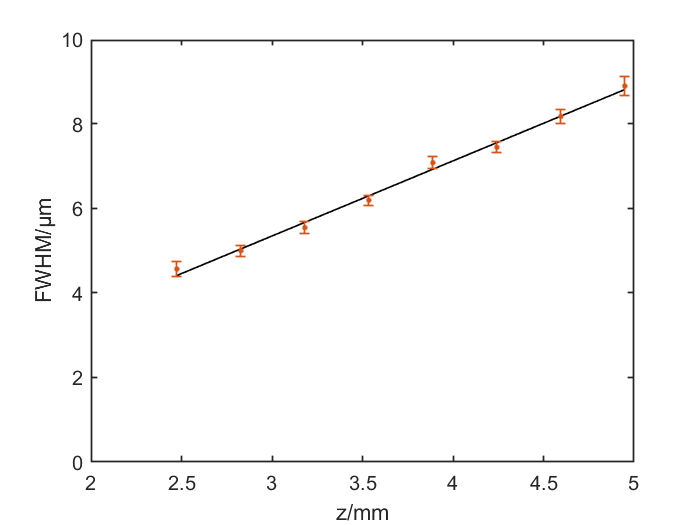


%Estimate of the true z position
z2_v=(4.5e3-z_v)*sqrt(2);

%Calculate the full width at half maximum
FWHM_v=sigma_z_v*2*sqrt(2*log(2));
FWHM_error_v=sigma_z_error_v*2*sqrt(2*log(2));


%Fit a straight line
[xData, yData] = prepareCurveData( z2_v, FWHM_v );

% Set up fittype and options.
ft = fittype( 'poly1' );
%ft = fittype( '2*sqrt(2*log(2))*sqrt((d/(2*sqrt(3)))^2+(b*x/sqrt(3))^2)', 'independent', 'x', 'dependent', 'y' );
excludedPoints = excludedata( xData, yData, 'Indices', [19 20] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
%opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult_v, gof] = fit( xData, yData, ft, opts );

lin_error_v=confint(fitresult_v,0.6827);


%Plot the FWHM
figure;plot(z2_v/1e3,fitresult_v(z2_v),'k','LineWidth',1)
hold on
errorbar(z2_v/1e3,FWHM_v,FWHM_error_v,'.','LineWidth',1,'MarkerSize',10)
ylabel(['FWHM/',char(181),'m'])
xlabel(['z/mm'])
%xlim([0 3.6])
ylim([0 10])
set(gca,'FontSize',12,'LineWidth',1)

Looks like a very straight line, no inidication of it turning over at these distance from the pinhole. Not surprising given how quickly the FWHM is increasing. 

TM estimated that the skimmer pinhole distance is 68-69mm and the skimmer diameter is about 200um.

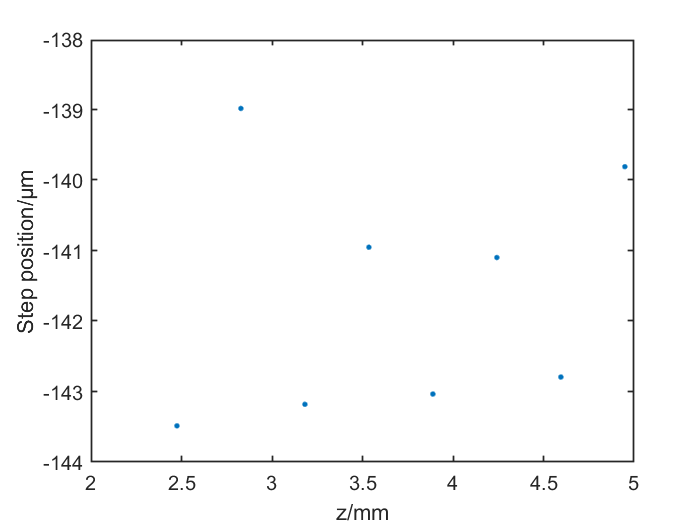

% %Estimate the pinhole size
% d_v=fitresult_v.p2*sqrt(3)/(sqrt(2*log(2)));
% d_v_error=(diff(lin_error_v(:,2))/2)*sqrt(3)/(sqrt(2*log(2)));

%Estimate angular source size
beta_v=fitresult_v.p1*sqrt(3)/(2*sqrt(2*log(2)));
beta_error_v=(diff(lin_error_v(:,1))/2)*sqrt(3)/(2*sqrt(2*log(2)));

beta_fwhm_v=fitresult_v.p1;
beta_error_fwhm_v=(diff(lin_error_v(:,1))/2);


%Estimate the size of the skimmer

r_skim_guess_v=beta_v*L;
r_skim_guess_error_frac_v=sqrt((beta_error_v/beta_v)^2+(L_error/L)^2);
r_skim_guess_error_v = r_skim_guess_error_frac_v*r_skim_guess_v;

%r_skim_fwhm_v=beta_v*68.5e-3;
%r_skim_guess_error_v=beta_error_v*68.5e-3;

d_skim_guess_v=r_skim_guess_v*2;
d_skim_guess_error_v=r_skim_guess_error_v*2;

%Plot the positions
figure;plot(z2_v/1e3,mu_z_v,'.','LineWidth',1,'MarkerSize',10)
ylabel(['Step position/',char(181),'m'])
xlabel(['z/mm'])
%xlim([1.9 3.6])
set(gca,'FontSize',12,'LineWidth',1)

## Plot the data together

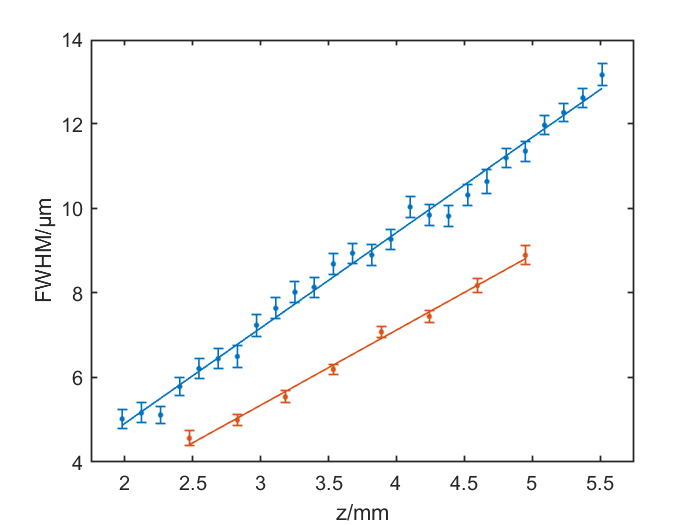


%Plot the FWHM
figure;plot(z2/1e3,fitresult_h(z2),'k','LineWidth',1,'Color',	[0, 0.4470, 0.7410])
hold on
errorbar(z2/1e3,FWHM,FWHM_error,'.','LineWidth',1,'MarkerSize',10,'Color',	[0, 0.4470, 0.7410])

plot(z2_v/1e3,fitresult_v(z2_v),'k','LineWidth',1,'Color', [0.8500, 0.3250, 0.0980])
hold on
errorbar(z2_v/1e3,FWHM_v,FWHM_error_v,'.','LineWidth',1,'MarkerSize',10,'Color', [0.8500, 0.3250, 0.0980])
%errorbar(z2(19:20)/1e3,FWHM(19:20),FWHM_error(19:20),'.','LineWidth',1,'MarkerSize',10,'Color',	[1, 0, 0])
ylabel(['FWHM/',char(181),'m'])
xlabel('z/mm')
xlim([1.75 5.75])
%ylim([0 14])
set(gca,'FontSize',12,'LineWidth',1)



% exportgraphics(gcf,'..\Figures\Beam_width_all.eps')
% savefig(['..\Figures\Beam_width_all.fig'])

% Export the data to an excel file

% T_h=table(z2',FWHM',FWHM_error',fitresult_h(z2));
% T_h.Properties.VariableNames={'z/mm','FHWM/um','FWHM Error/um','Model FWHM/um'}
% 
% T_v=table(z2_v',FWHM_v',FWHM_error_v',fitresult_v(z2_v));
% T_v.Properties.VariableNames={'z/mm','FHWM/um','FWHM Error/um','Model FWHM/um'}
% 
% excel_filename='FWHM_excel.xlsx';
% 
% writetable(T_h,excel_filename,'sheet','Horizontal','range','A1:D26')
% writetable(T_v,excel_filename,'sheet','Vertical','range','A1:D8')

% Looking at difference in vertical and horizontal beam divergences
% N_points=100000;
% vert_points=NaN*zeros(N_points,1);
% hori_points=NaN*zeros(N_points,1);
% %angle_pred=NaN*zeros(N_points,1);
% 
% for n_points=1:N_points
%     hori_points(n_points)=normrnd(beta_fwhm/(2*sqrt(2*log(2))),beta_error_fwhm/(2*sqrt(2*log(2))));
%     vert_points(n_points)=normrnd(beta_fwhm_v/(2*sqrt(2*log(2))),beta_error_fwhm_v/(2*sqrt(2*log(2))));
% end
% 
% angle_pred=acosd(vert_points./hori_points);
% 
% figure;histogram(angle_pred)
% hold on
% xline(acosd(beta_fwhm_v/beta_fwhm))
% xlabel('Angle/^\circ')
% ylabel('Frequency')
% 
% angle_prob=sum(angle_pred>45)/length(angle_pred)

Generate an ellipse and see if it is the right scale difference

% x_limit=2;
% y_limit=2;
% 
% N_gen=500;
% 
% 
% %r_gen=0.1;
% 
% x_gen=linspace(-x_limit,x_limit,N_gen);
% y_gen=linspace(-y_limit,y_limit,N_gen);
% 
% r_pin=0.1;
% 
% % angle_vec=linspace(0,60,30);
% % N_angle=length(angle_vec);
% 
% r_gen_vec=linspace(0.01,0.5,60);
% N_r_gen=length(r_gen_vec);
% 
% ratio=NaN*zeros(N_angle,1);
% width_x=NaN*zeros(N_angle,1);
% width_y=NaN*zeros(N_angle,1);
% 
% % for n_angle=1:N_angle
% for n_r_gen=1:N_r_gen
%     
%     %angle_gen=angle_vec(n_angle);
%     angle_gen=45;
%     
%     r_gen=r_gen_vec(n_r_gen);
%     
%     [X_gen,Y_gen] = meshgrid(x_gen,y_gen);
%     
%     Z_gen=(sqrt((X_gen*cosd(angle_gen)).^2+Y_gen.^2)<(r_gen));
%     
%     Z_gen2=(sqrt((X_gen).^2+Y_gen.^2)<(r_pin));
%     
%     Z_gen=conv2(Z_gen,Z_gen2,'same');
%     
%     % figure;imagesc(Z_gen);axis equal tight;colormap gray
%     
%     % Integrate over y direction
%     X_int=sum(Z_gen);
%     X_cumsum=cumsum(X_int)/sum(X_int);
%     %figure;plot(x_gen,X_cumsum)
%     
%     % Integrate over x direction
%     Y_int=sum(Z_gen,2);
%     Y_cumsum=cumsum(Y_int)/sum(Y_int);
%     %figure;plot(y_gen,Y_cumsum)
%     
%     %Fit error functions
%     [xData, yData] = prepareCurveData( x_gen, X_cumsum );
%     
%     % Set up fittype and options.
%     ft = fittype( 'normcdf(x,mu,sigma)', 'independent', 'x', 'dependent', 'y' );
%     opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
%     opts.Display = 'Off';
%     opts.StartPoint = [0 0.1];
%     
%     % Fit model to data.
%     [fitresult_x, gof] = fit( xData, yData, ft, opts );
%     
%     %figure;plot( fitresult_x, xData, yData );
%     
%     [xData_y, yData_y] = prepareCurveData( y_gen, Y_cumsum );
%     
%     % Set up fittype and options.
%     ft = fittype( 'normcdf(x,mu,sigma)', 'independent', 'x', 'dependent', 'y' );
%     opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
%     opts.Display = 'Off';
%     opts.StartPoint = [0 0.1];
%     
%     % Fit model to data.
%     [fitresult_y, gof_y] = fit( xData_y, yData_y, ft, opts );
%     
%     %figure;plot( fitresult_y, xData_y, yData_y );
%     
%     %Ratio of the widths
%     
% %     width_y(n_angle)=fitresult_y.sigma;
% %     width_x(n_angle)=fitresult_x.sigma;
% %     ratio(n_angle)=fitresult_y.sigma/fitresult_x.sigma;
% 
%     width_y(n_r_gen)=fitresult_y.sigma;
%     width_x(n_r_gen)=fitresult_x.sigma;
%     ratio(n_r_gen)=fitresult_y.sigma/fitresult_x.sigma;
% end
% 
% figure;plot(r_gen_vec./r_pin,1./ratio,'LineWidth',1)
% %yline(1/(beta_fwhm_v/beta_fwhm),'k--','LineWidth',1)
% yline(1./cosd(angle_gen),'k--','LineWidth',1)
% % hold on
% % plot(angle_vec,cosd(angle_vec))
% % xlabel('Angle/^\circ')
% xlabel('Demagnified source size/pinhole size')
% ylabel('Beam width ratio')
% set(gca,'FontSize',12,'LineWidth',1)
% 
% 
% figure;plot(r_gen_vec./r_pin,width_x./r_pin,'LineWidth',1)
% hold on
% plot(r_gen_vec./r_pin,width_y./r_pin,'LineWidth',1)
% xlabel('Demagnified source size/pinhole size')
% ylabel('Beam width/pinhole size')
% set(gca,'FontSize',12,'LineWidth',1)